# Sample 6-6

## 標本化

二変量アップサンプリング

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Sampling

Bivariate upsampling

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

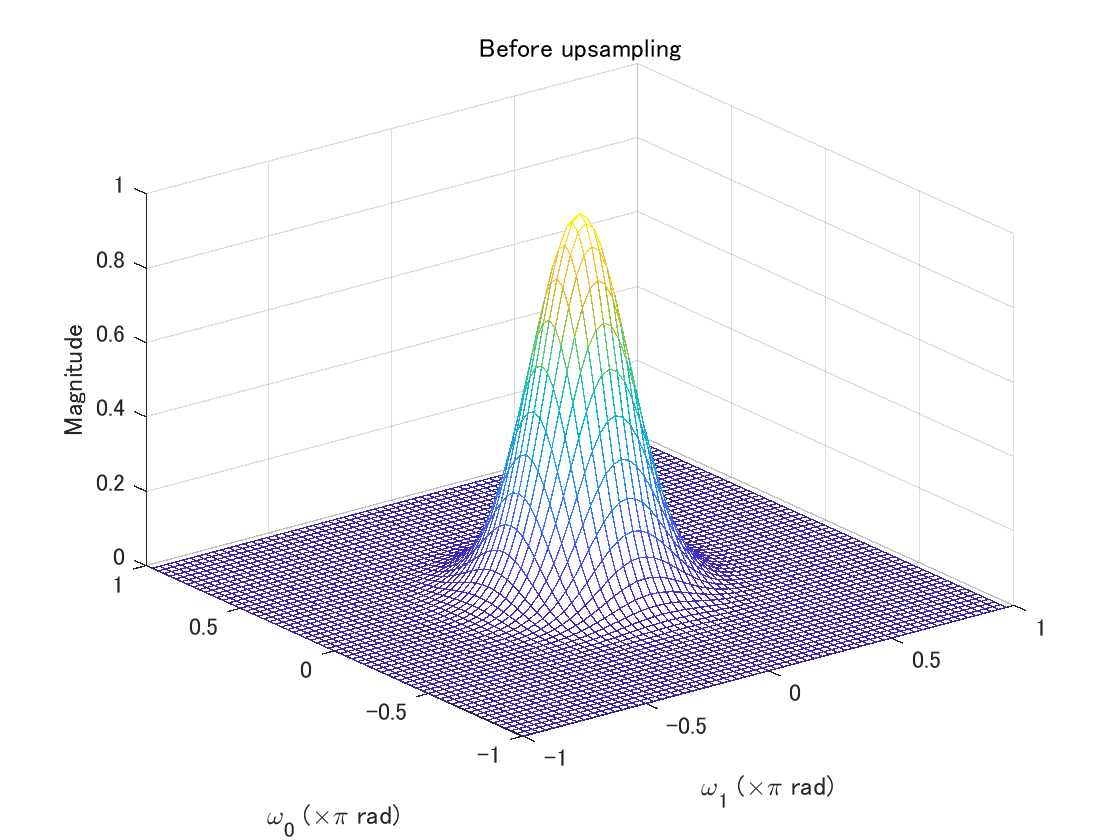

%% パラメータ設定
% 垂直の補間率
verticalInpFactor = 3;
% 水平の補間率
horizontalInpFactor = 2;

% 配列の標準偏差
sigma = 2;
% 配列のサイズ
sizeX = 31;

%% 2次元ガウス関数による配列の生成
arrayX = fspecial('gaussian',sizeX,sigma);

%% 原信号の周波数振幅特性
figure(1)
freqz2(arrayX)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('Before upsampling')

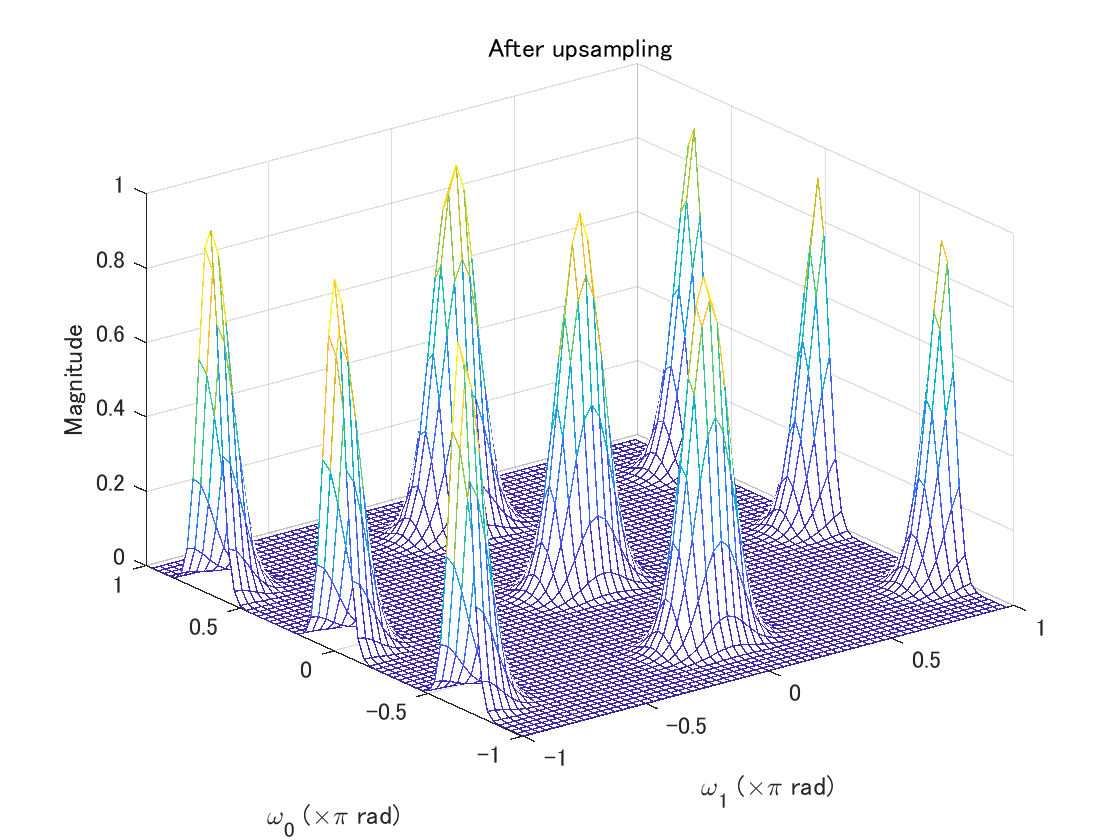

%% アップサンプリング
arrayY = ...
    upsample(...
        upsample(arrayX,...
            verticalInpFactor).',...
               horizontalInpFactor).';

%% 処理後の周波数振幅特性
figure(2)
freqz2(arrayY)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('After upsampling')

        
% end

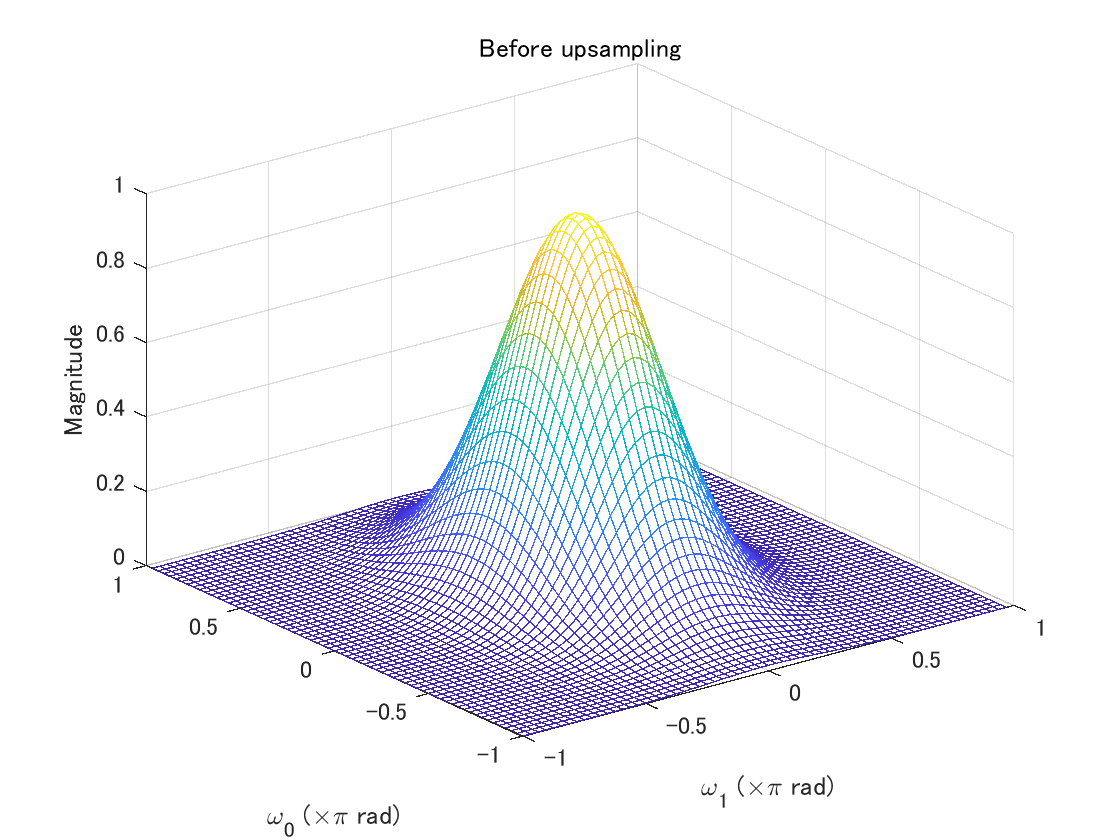

%% 補間行列（2x2)
upMtx = [ 1 1 ; -1 1 ];

%% 配列の共分散行列
covMtx  = [2 0 ; 0 1];

%% 配列のサイズ
sizeX = 31;

%% 2次元ガウス関数による配列の生成
arrayX = gaussian2cq(sizeX,covMtx);

%% 原信号の周波数振幅特性
figure(1)
freqz2(arrayX)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('Before upsampling')

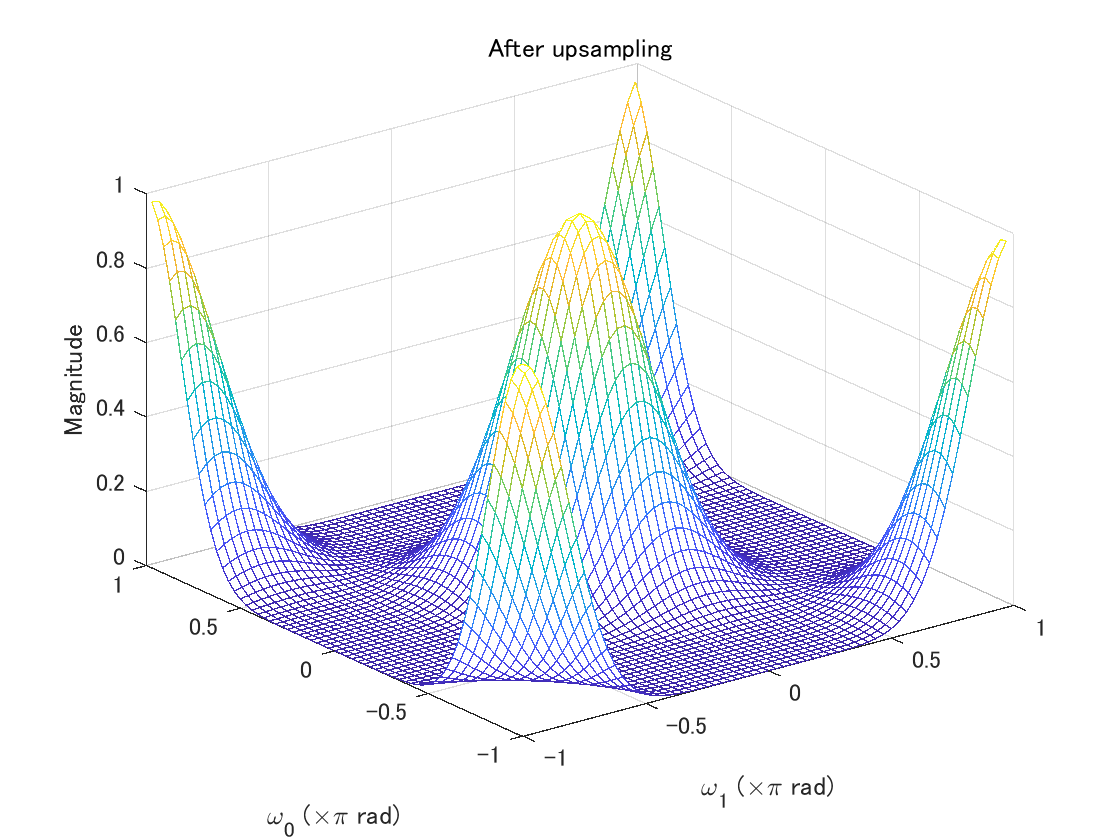


%% 2次元アップサンプリング
arrayY = upsample2(arrayX,upMtx);

% 処理後の周波数振幅特性
figure(2)
freqz2(arrayY)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('After upsampling')

function x = gaussian2cq(sizeX, covMtx)
% GAUSSIAN2CQ
%
% Inputs
%
%   sizeX: size of output array 
%   covMtx: covariance matrix
%
% Output
%
%   x: array generated by Gauss Func. 
%
% $Id: gaussian2cq.m,v 1.1 2006/06/13 10:21:10 sho Exp $
%
% Copyright (C) 2005-2015 Shogo MURAMATSU, All rights reserved
%
sizeHalf = floor(sizeX / 2);

if isscalar(covMtx)
    covMtx = covMtx * eye(2);
end

x = zeros(sizeHalf*2);
iRow = 1;
for n1 = -sizeHalf:sizeHalf
    iCol = 1;
    for n0 = -sizeHalf:sizeHalf    
        p = - 0.5 * [ n0 n1 ] * (covMtx\[ n0 n1 ].');
        x(iRow,iCol) = exp(p);
        iCol = iCol + 1;
    end
    iRow = iRow + 1;
end
x = x / sum(sum(x));

end %of gaussian2cq

function [outputArray, X, Y] = upsample2(inputArray,upMtx)
%
% Inputs
%
%   inputArray: input array
%   upMtx: upsampling matrix
%
% Outputs
%
%   outputArray: output array 
%   X          : horizontal sampling points
%   Y          : vertical sampling points
%
% $Id: upsample2.m,v 1.2 2007/05/07 11:09:47 sho Exp $
%
% Copyright (C) 2005-2007 Shogo MURAMATSU, All rights reserved
%

% 入力配列のサイズ
nRowsInputArray = size(inputArray,1);
nColsInputArray = size(inputArray,2);
nCompInputArray = size(inputArray,3);

% アップサンプリング後の配列範囲計算
vertexPoints(:,1) = [ 0 0 ].';
vertexPoints(:,2) = upMtx * [ 0 nColsInputArray ].';
vertexPoints(:,3) = upMtx * [ nRowsInputArray 0 ].';
vertexPoints(:,4) = upMtx * [ nRowsInputArray nColsInputArray ].';
minPoint = floor(min(vertexPoints,[],2));
maxPoint = ceil(max(vertexPoints,[],2))-1;

% アップサンプリング
clear arrayY;
iRow = 1;
for m0 = minPoint(1):maxPoint(1)
    iCol = 1;
    for m1 = minPoint(2):maxPoint(2)
        outputArray(iRow, iCol, :) = zeros(1,nCompInputArray,...
                'like',inputArray);        
        originalPoint = upMtx \ [ m0 m1 ].';
        lat = upMtx * fix(originalPoint);
        if m0 == lat(1) && m1 == lat(2)
            n0 = originalPoint(1);
            n1 = originalPoint(2);
            if n0 >= 0 && n0 < nRowsInputArray  && ...
                n1 >= 0 && n1< nColsInputArray
                outputArray(iRow, iCol, :) = inputArray(n0 + 1, n1 + 1, :);    
            end
        end
       iCol = iCol + 1;
    end
    iRow = iRow + 1;
end

Y = minPoint(1):maxPoint(1);
X = minPoint(2):maxPoint(2);

end % of upsample2

© Copyright, Shogo MURAMATSU, All rights reserved.